# Constant illumination method for consistent exposure

% This program visualizes the first exposure method explained in my thesis.
% This method considers a constant exposure time and illumination.


## Calculations and visualisation

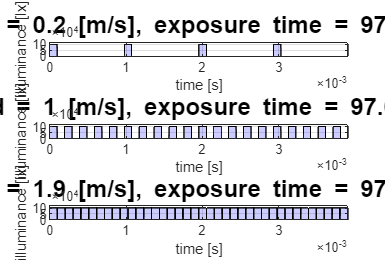

% The following parameters can be adjusted:
illuminance = 102400;           % [lx]
t_exp = 1/10240;                % exposure time [s]
conv_speed = [0.2, 1, 1.9];     % conveyor belt speed [m/s]
pixel_size = 0.4/4096;          % physical representation of pixel [m]
pixels_trigger = 2;             % Every trigger acquires two rows of pixels
num_of_periods = 4;             % number of periods shown in top graph

trig_freq = conv_speed./(pixel_size*pixels_trigger);     % Trigger frequency [Hz]
T_trig = 1./trig_freq;                                   % trigger period [s]

hold on

for i = 1:length(conv_speed)
    subplot(length(conv_speed), 1, i)

    t = linspace(0, T_trig(1)*num_of_periods, 5000);
    LSC_exp = PWM(trig_freq(i), 0, illuminance, t_exp*100/T_trig(i), t);

    fill_handle_LSC = fill([t fliplr(t)], [LSC_exp zeros(size(LSC_exp))], 'b', 'FaceAlpha', 0.2);
    
    ylim([0 120000])
    xlim([0 T_trig(1)*num_of_periods])
    title("\fontsize{16}Speed = " + conv_speed(i) + " [m/s], exposure time = " + round(t_exp*1000000, 2) + " [µs]")
    ylabel("illuminance [lx]")
    xlabel("time [s]")
    grid on
end

hold off